# Neural Networks

Load the pump features from `pumpFeatures.`

rng(3)
dataTrain = readtable("data\pumpFeaturesNets.xlsx", Sheet="dataTrain");
dataTest = readtable("data\pumpFeaturesNets.xlsx", Sheet="dataTest");
dataVal = readtable("data\pumpFeaturesNets.xlsx", Sheet="dataVal");

The data has been divided into 3 sets: train, validation and test

whos dataTrain dataVal dataTest

  Name             Size             Bytes  Class    Attributes

  dataTest       150x85            122321  table              
  dataTrain      700x85            496321  table              
  dataVal        150x85            122321  table              



## Task 1 - 3

To fit a neural network for classification in MATLAB, use the `fitcnet` function with the table as input and specify the name of the response variable. By default, a neural network with one hidden layer consisting of 10 neurons is created. To specify the number of hidden neurons in the network, use the `"LayerSizes"` property:

`nnModel` `=` `fitcnet``(``tableData``,``...`

    `"ResponseVariable"``,``...`

    `"LayerSizes"``,``24``)``;`

Notice that all the observations in the test set were classified into one class. Neural networks require data to be standardized, otherwise they fail to converge to a solution. To address this, you can set the `"Standardize"` property to `true`.

`nnModel` `=` `fitcnet``(``tableData``,``...`

    `"ResponseVariable"``,``...`

    `"LayerSizes"``,``24``,``...`

    `"Standardize"``,``true``)``;`

To prevent overfitting a neural network, it is a good practice to use a validation set to stop training once the validation loss stops improving. You can use the `"ValidationData"` property to specify the data used for validation. Setting the `"ValidationPatience"` property tells the network to stop training if the validation loss has not improved after a certain number of iterations.

mdlNet = fitcnet(dataTrain, "faultCode",...
    "LayerSizes", 48,...
    "Standardize", true,...
    "ValidationData", dataVal,...
    "ValidationPatience", 30);

Evaluate model

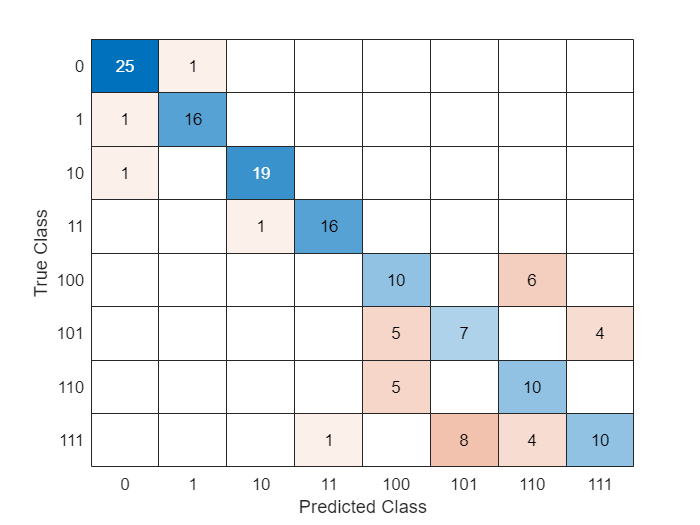

Training Error: 0.13571
Loss: 0.22832


evalModel(dataTest, mdlNet)

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + resubLoss(mdl))
    disp("Loss: " + loss(mdl, dataTest))
end